# Retratos de fase con la función PhasePortrait

# 1. Para modelos con 2 estados

#### Presa - Depredador

Para realizar los retratos de fase, se utilizará el modelo clásico de presa depredador de Lotka-Volterra.


$$\dot{P}(t)= \alpha P(t) - \beta P(t)D(t)\\
\dot{D}(t)= \delta P(t) D(t) - \gamma D(t)$$


**Con los siguientes parámetros y estados:**

$P(t)$: Número de presas en el tiempo

$D(t)$: Depredadores en el tiempo

$\alpha$: Tasa instantánea de aumento de presas en ausencia de depredadores

$\beta$: Tasa de cacería de número de presas por depredador

$\delta$: Tasa de aumento de depredadores por presa cazada

$\gamma$: Tasa instantánea de disminución de depredadores en ausencia de presas

**1. **Creación del modelo como una handle function a partir de una función ya existente

addpath("funciones")


f = @PresaDepredador;           % Modelo creado a partir de la funcion PresaDepredador

**2.** Se definen los parámetros para realizar el retrato de fase

intervalX1 = 0 : 0.2 : 5;       % Intervalo para estado 1 (x1)
intervalX2 = 0 : 0.2 : 5;       % Intervalo para estado 2 (x2)

X = [intervalX1; intervalX2];   % Los intervalos se guardan en una matriz 

**3.** Se definen los parámetros para graficar trayectorias de estado sobre el retrato de fase

Simulation = [0, 30, 1000];     % Se define el tiempo inicial, final y tamaño de
                                % Los intervalos de muestreo para simular
                                % las trayectorias

%Definicion de las condiciones iniciales como una celda                              
IC = {};
IC{1} = 1;                      % Condicion inicial para primer estado
IC{2} = [0, 1, 3];              % Condiciones iniciales para segundo estado, este es el unico estado 
                                % que se puede variar en diferentes rangos de valores

**4.** Usar la función de retrato de fase

help PhasePortrait

  PhasePortrait(Modelfunction, ModelDimension, StateIntervals, SimulationSet,...
                InitialContidions, PlotTrajectories)
 
  Modelfunction: pass the function of the interest model. For example a
                 handle function or a .m file.
  ModelDimension: an integer with the number of model equations (2 or 3).
  StateIntervals: a nxd matrix, where n is the modelDimension and d is the
                  number of state variations
  SimulationSet: a vector with initial time, final time, and sample size. 
  InitialContidions: a cell array with the initial values, only available
                     for the last state
  PlotTrajectories: boolean (true or false) for plotting the simulation of
                    state trajectories



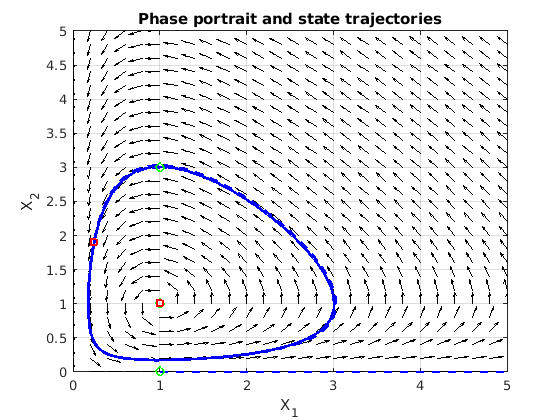

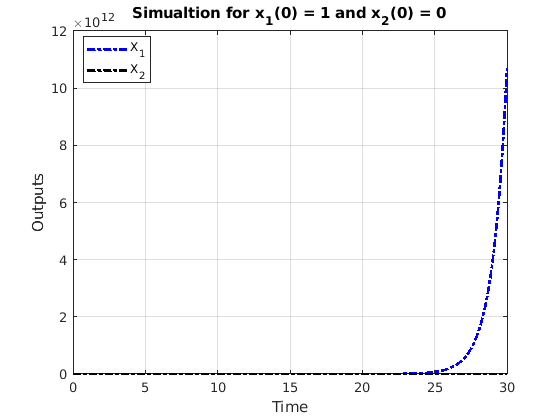

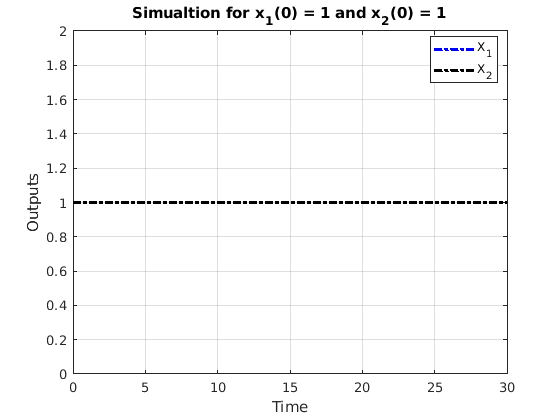

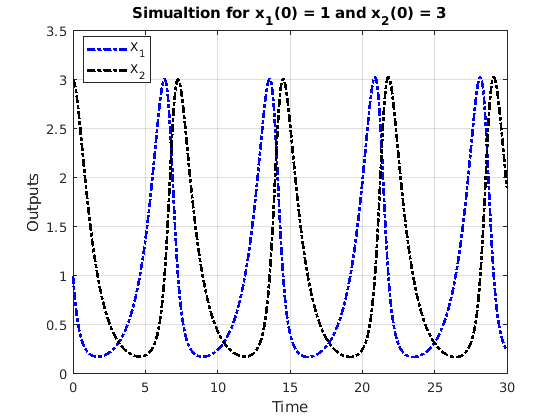

PhasePortrait(f, 2, X, Simulation, IC, true);

# 2. Para modelos con 3 estados

En este caso se utiliza como ejemplo el modelo de [Lorenz](https://mathworld.wolfram.com/LorenzAttractor.html) de 3 estados:


$$\dot{X} = \delta (Y - X)\\
\dot{Y} = X(\rho - Z) - Y\\
\dot{Z} = XY - \beta Z$$


**1. **Creación del modelo como una handle function

%valor de los parámetros del modelo
params = [6  %delta
          23 %rho
          10 %beta
          ];
%Handle function (modelo)
%el vector x representa las variables de estado
%el modelo se escribe de manera vectorial
f = @(t,x) [
    params(1)*(x(2)-x(1));
    x(1)*(params(2) - x(3)) - x(2);
    x(1)*x(2) - params(3)*x(3);
    ];

**2.** Se definen los parámetros para realizar el retrato de fase

intervalX1 = -60 : 10 : 60; % intervalo para estado 1 (x1)
intervalX2 = -60 : 10 : 60; % intervalo para estado 2 (x2)
intervalX3 = -60 : 10 : 60; % intervalo para estado 3 (x3)

X = [intervalX1; intervalX1; intervalX3]; % Los intervalos se guardan en una matriz 

**3.** Se definen los parámetros para graficar trayectorias de estado sobre el retrato de fase

Simulation = [-50, -45, 1000];  % Se define el tiempo inicial, final y tamaño de
                                % Los intervalos de muestreo para simular
                                % las trayectorias

%Definicion de las condiciones iniciales como una celda    
IC = {};
IC{1} = -10;                    % Condicion inicial para primer estado
IC{2} = 0;                      % Condicion inicial para segundo estado
IC{3} = [-60 0 60];             % Condiciones iniciales para tercer estado, este es el unico estado 
                                % que se puede variar en diferentes rangos de valores

**4.** Usar la función de retrato de fase, la cual presenta la siguiente estructura y parámetros:

help PhasePortrait

  PhasePortrait(Modelfunction, ModelDimension, StateIntervals, SimulationSet,...
                InitialContidions, PlotTrajectories)
 
  Modelfunction: pass the function of the interest model. For example a
                 handle function or a .m file.
  ModelDimension: an integer with the number of model equations (2 or 3).
  StateIntervals: a nxd matrix, where n is the modelDimension and d is the
                  number of state variations
  SimulationSet: a vector with initial time, final time, and sample size. 
  InitialContidions: a cell array with the initial values, only available
                     for the last state
  PlotTrajectories: boolean (true or false) for plotting the simulation of
                    state trajectories



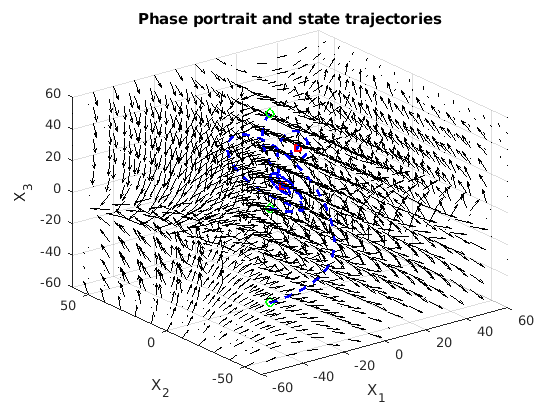

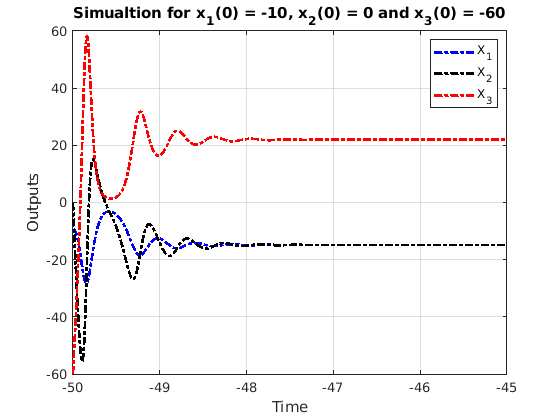

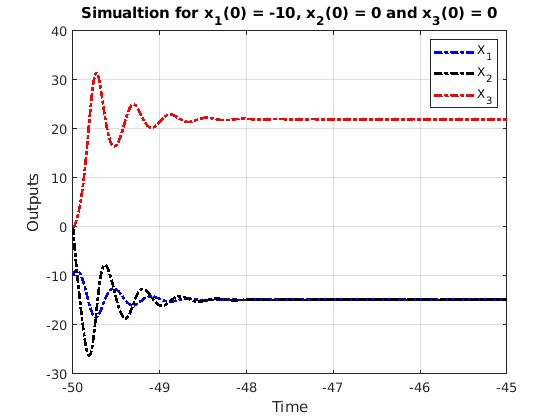

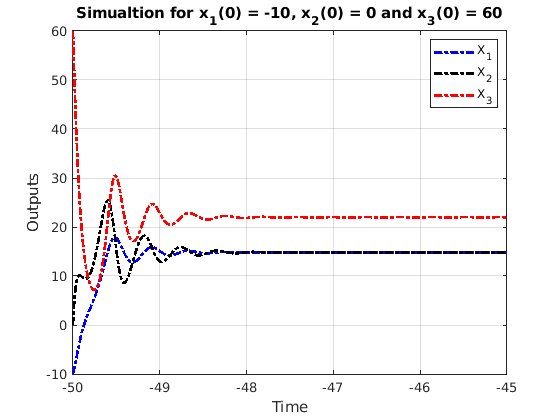

PhasePortrait(f, 3, X, Simulation, IC, true);